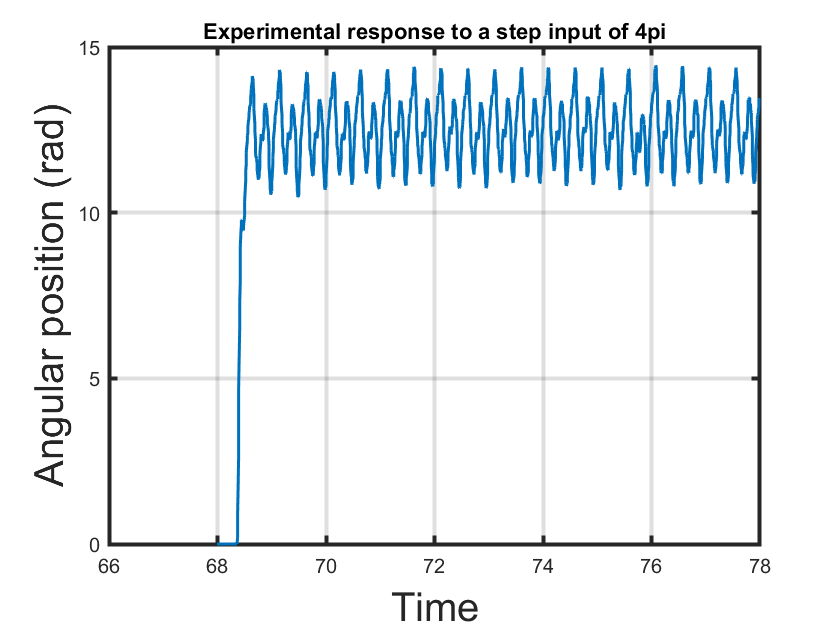

clear;
close all;

[velocity] = xlsread("velocity1.xlsx");

cola = velocity(1:end, 1);
colb = velocity(1:end, 2);
colc = linspace(1,1,length(cola));

figure(1);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
% plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Experimental response to a step input of 4pi")
grid on;
set(gca,'linewidth',2)

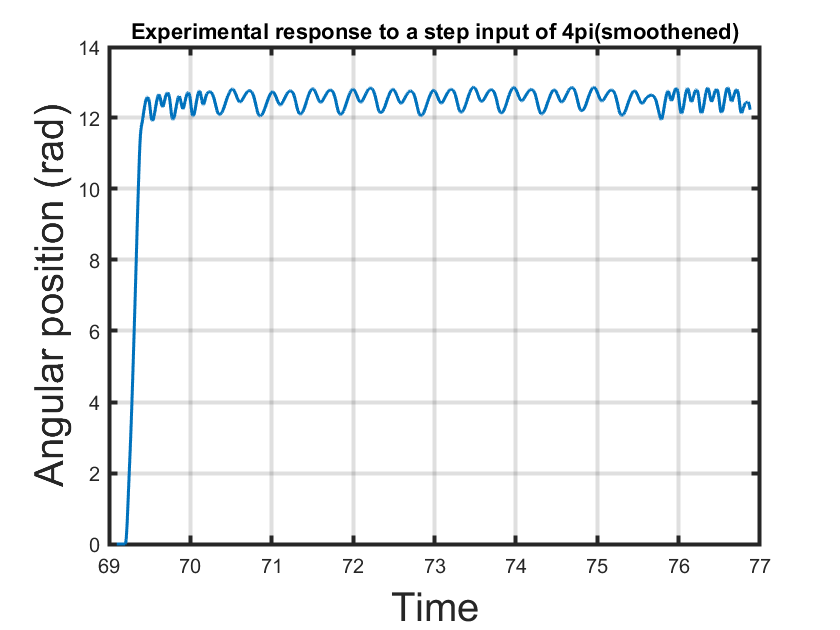


cola = smoothdata(velocity(1:end, 1));
colb = smoothdata(velocity(1:end, 2));
colc = linspace(1,1,length(cola));

figure(2);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
% plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Experimental response to a step input of 4pi(smoothened)")
grid on;
set(gca,'linewidth',2)

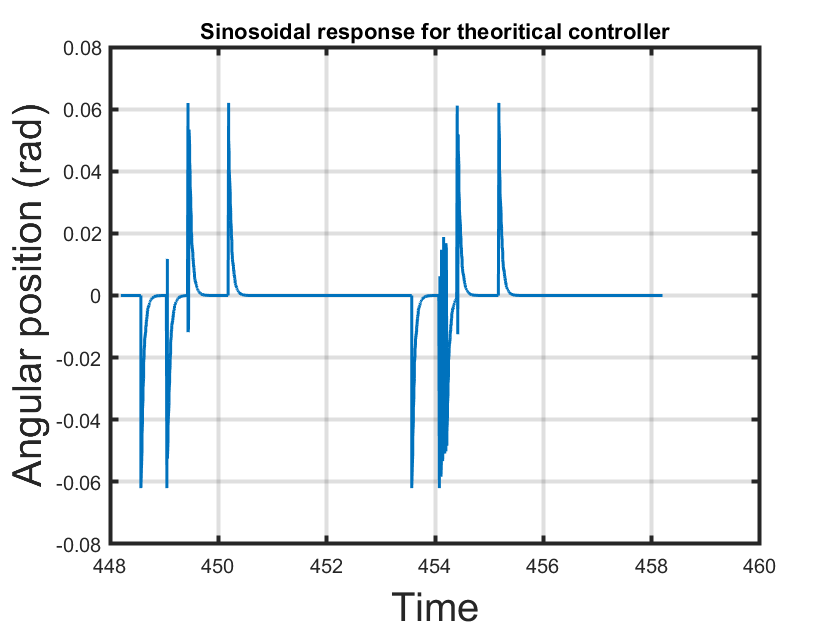


[sine] = xlsread("initial_sine.xlsx");

cola = sine(1:end, 1);
colb = sine(1:end, 2);
colc = linspace(1,1,length(cola));

figure(3);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
% plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Sinosoidal response for theoritical controller")
grid on;
set(gca,'linewidth',2)

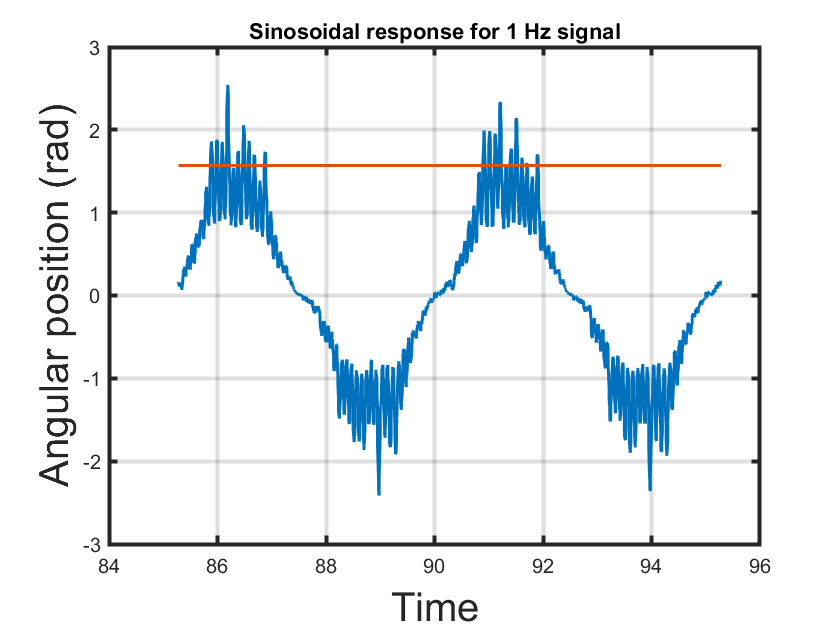

[velo1] = xlsread("velocity_1hz.xlsx");

cola = velo1(1:end, 1);
colb = velo1(1:end, 2);
colc = linspace(1.57,1.57,length(cola));

figure(4);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Sinosoidal response for 1 Hz signal")
grid on;
set(gca,'linewidth',2)

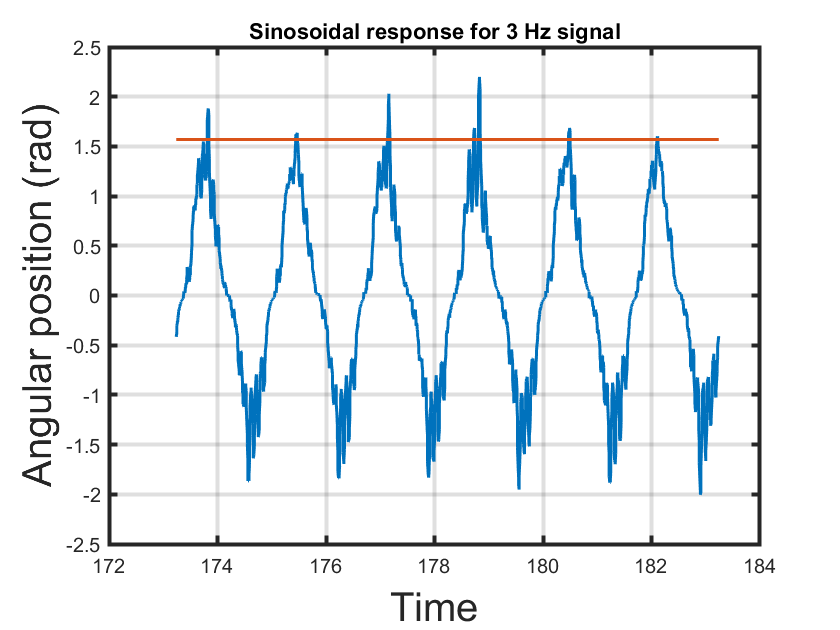


[velo2] = xlsread("velocity_3hz.xlsx");
cola = velo2(1:end, 1);
colb = velo2(1:end, 2);
colc = linspace(1.57,1.57,length(cola));
figure(5);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Sinosoidal response for 3 Hz signal")
grid on;
set(gca,'linewidth',2)

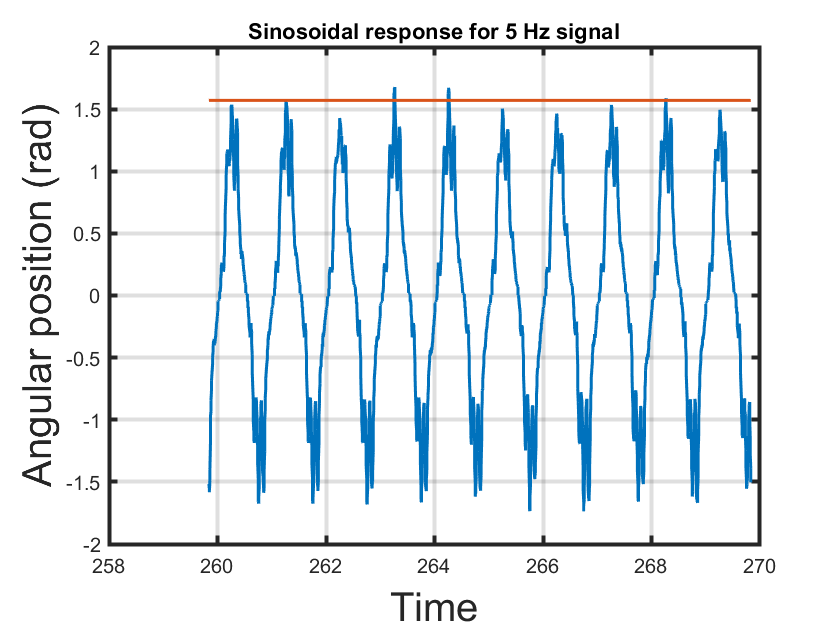


[velo3] = xlsread("velocity_5hz.xlsx");
cola = velo3(1:end, 1);
colb = velo3(1:end, 2);
colc = linspace(1.57,1.57,length(cola));
figure(6);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Sinosoidal response for 5 Hz signal")
grid on;
set(gca,'linewidth',2)

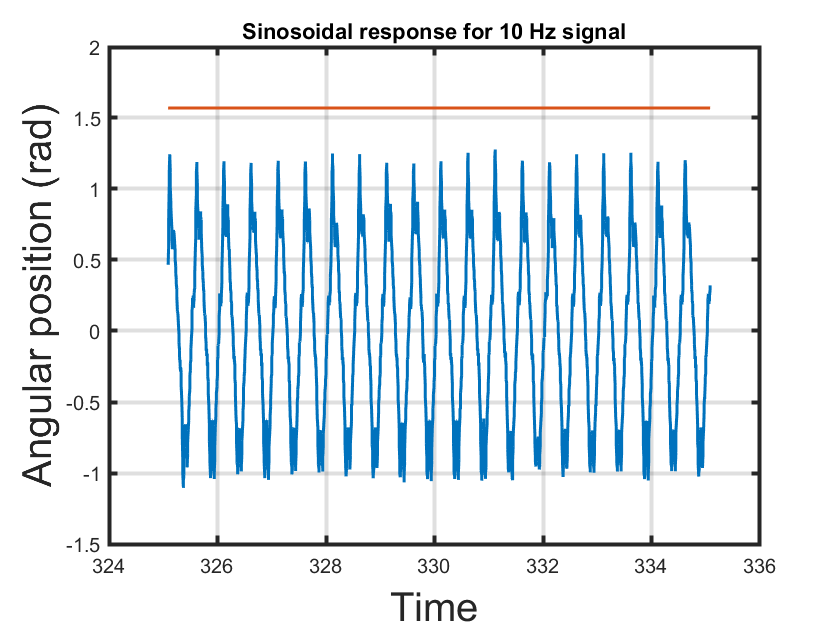


[velo4] = xlsread("velocity_10hz.xlsx");
cola = velo4(1:end, 1);
colb = velo4(1:end, 2);
colc = linspace(1.57,1.57,length(cola));
figure(7);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Sinosoidal response for 10 Hz signal")
grid on;
set(gca,'linewidth',2)

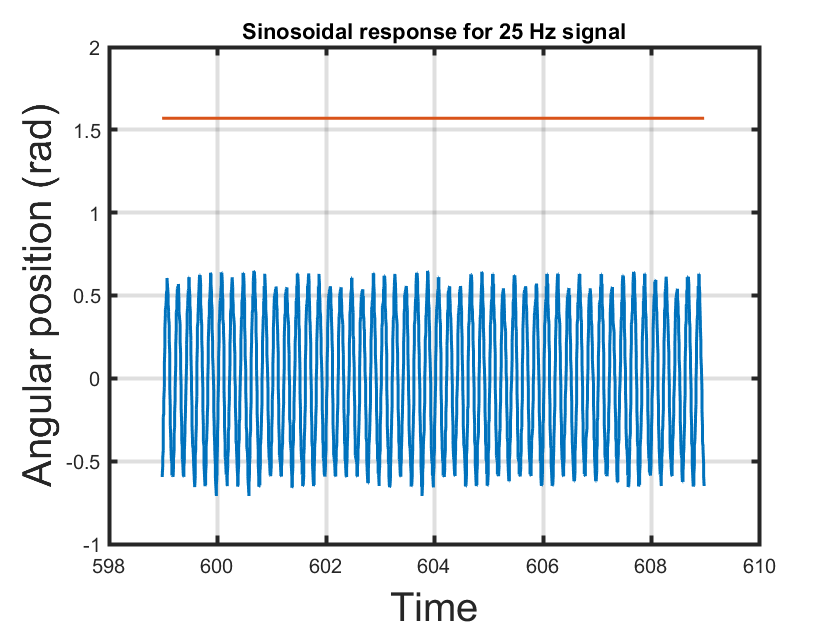


[velo5] = xlsread("velocity_25hz.xlsx");
cola = velo5(1:end, 1);
colb = velo5(1:end, 2);
colc = linspace(1.57,1.57,length(cola));
figure(8);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Sinosoidal response for 25 Hz signal")
grid on;
set(gca,'linewidth',2)

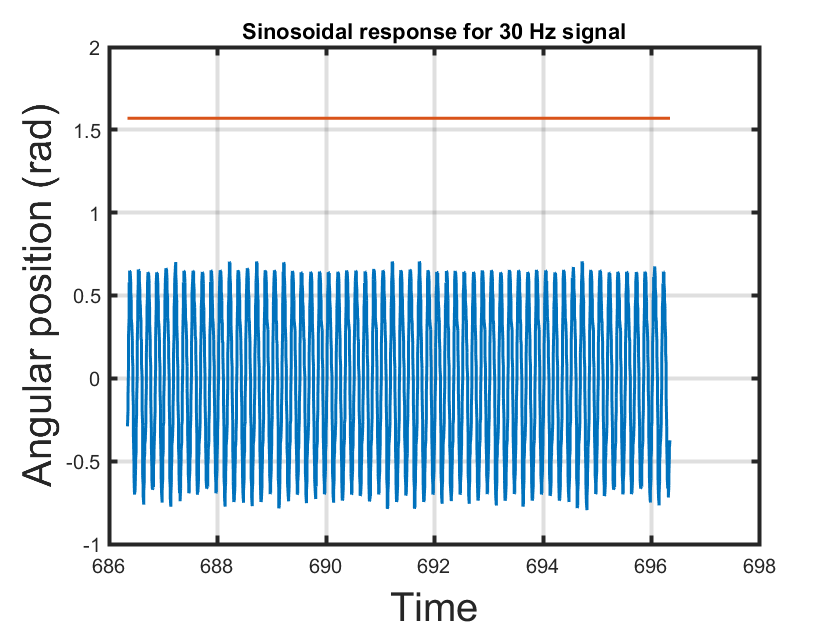


[velo6] = xlsread("velocity_30hz.xlsx");
cola = velo6(1:end, 1);
colb = velo6(1:end, 2);
colc = linspace(1.57,1.57,length(cola));
figure(9);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Sinosoidal response for 30 Hz signal")
grid on;
set(gca,'linewidth',2)

V = [0.25 0.5 0.75];
i_monitor = [0.23 0.47 0.72];
i_probe = [0.233 0.464 0.701];
i_avg = (i_monitor + i_probe) / 2;
K_a = mean(i_avg ./ V);

% Motor Properties
K_t = 4.24e-2; % Nm/A
J = 8.5e-6; %Kg-m^2
b = 3.7e-6; % Nm-s damping constant
G_s = tf([K_t*K_a],[J,b,0]);


K = 0.04421;
z1 = 1;
p1 = 0;
z2 = 1.6;
p2 = 5;
C = K*tf([1 1.2 0.04421],[0 5 1])

C =
 
                            
  0.04421 s^2 + 0.05305 s   
                            
                  + 0.001955
                            
  --------------------------
                  
           5 s + 1
                  
 
Continuous-time transfer function.



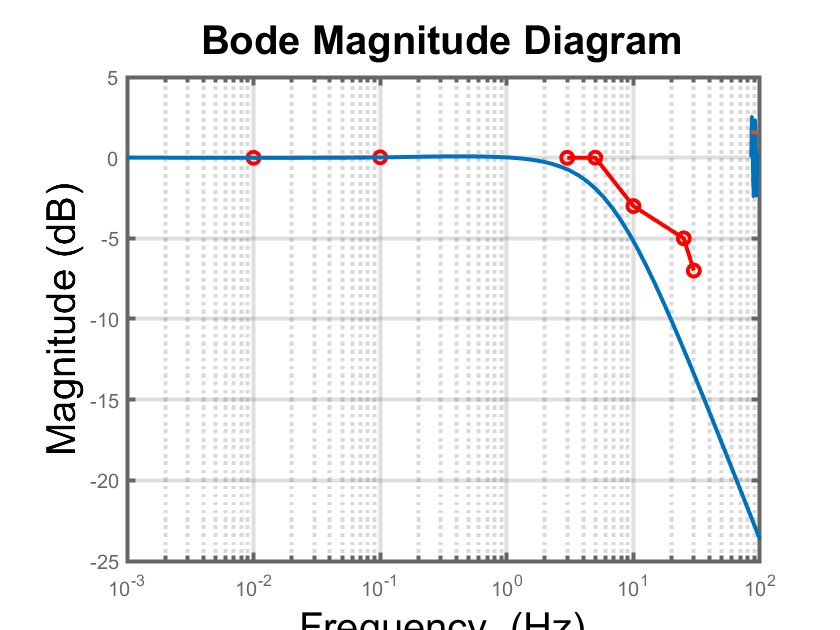

h = feedback(C*G_s,1);

fr = [.01,0.1,-1,3,5,10,25,30];
value = [-0.01,0.02,0.01,-0.01,0,-3,-5,-7];

figure(4);  grid on; box on; hold on;
set(gca,'linewidth',2)
plot(fr,value,'-ro')
G = bodeplot(h);
setoptions(G,'FreqUnits','Hz','PhaseVisible','off','Grid','on');
ylabel('Phase','FontSize',20)
xlabel('Frequency','FontSize',20)
title('Bode Magnitude Diagram','FontSize',20)
set(findall(gcf,'type','line'),'Linewidth',2);

set(gca,'linewidth',2)